clc;
clear;
close all;

del_t = 0.4 * 10^-3;        % this sampling period will be used to calculate the frequency range
n = linspace(-8, 7, 16);    

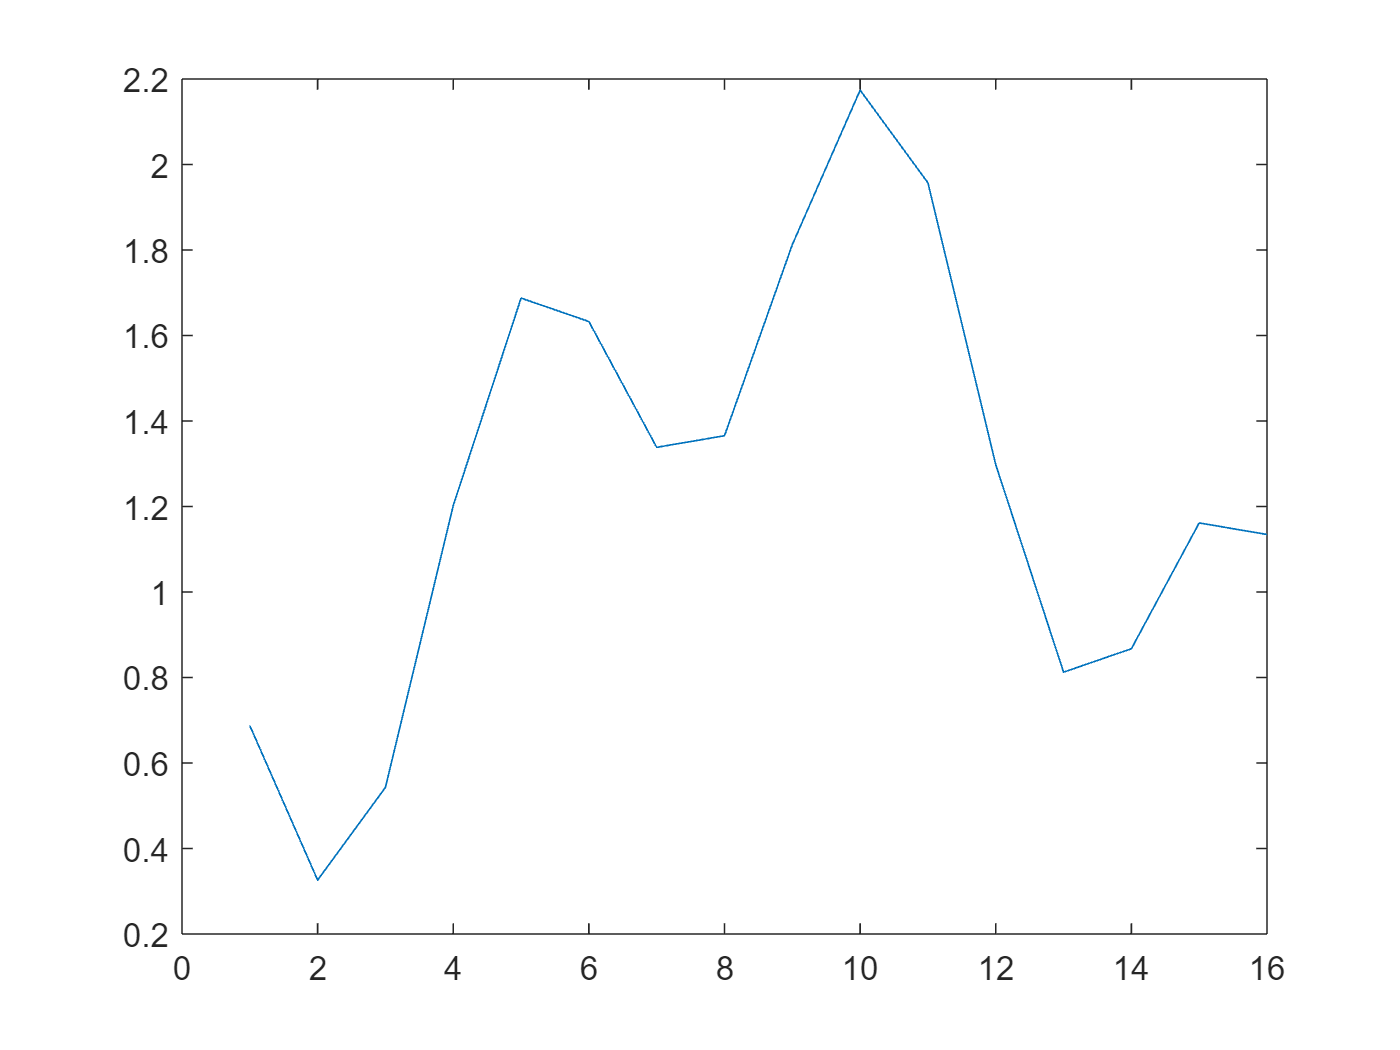

sampled_time_v = [0.6875, 0.3261, 0.5429, 1.2022, ...
    1.6875, 1.6327, 1.3384, 1.3655, 1.8125, 2.1739, 1.9571, ...
    1.2978, 0.8125, 0.8673, 1.1616, 1.1345]; %9th sample is t=0 origin.

L = length(sampled_time_v);
fqs = 1/del_t * 1/L * (-L/2:L/2-1); %  / (sample period * Number of samples)
figure;
plot(sampled_time_v)

%Testing update speed

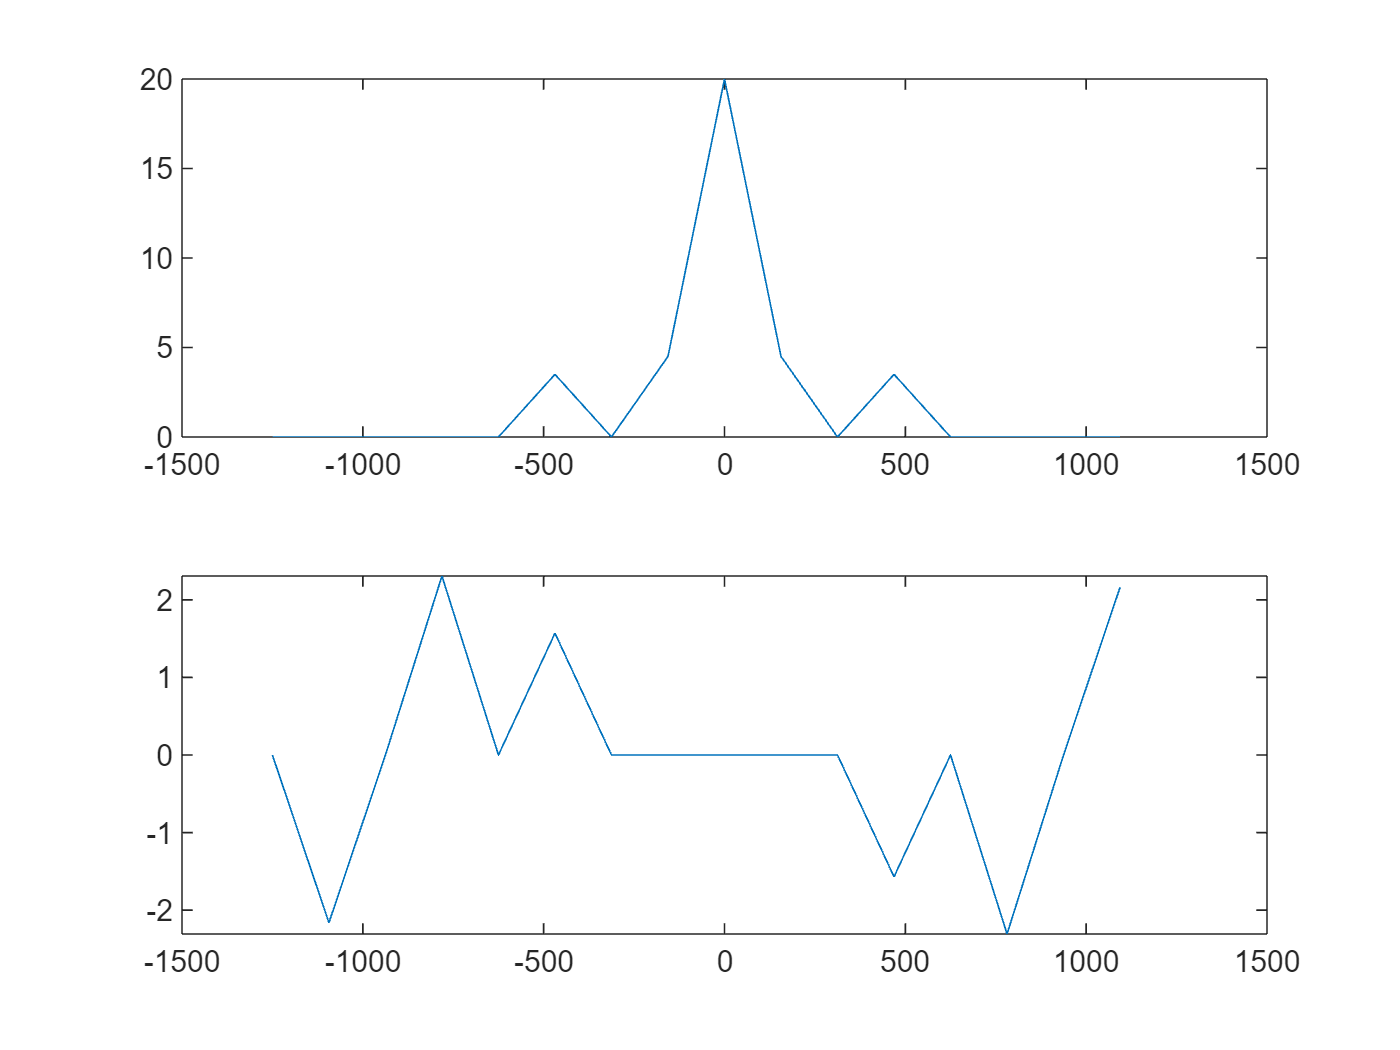

fft = fft(fftshift(sampled_time_v)); %fftshift swaps left and right halves of vector. here, 9:16 get moved to front
figure;                              %thus array goes from 1:16 to 9:16then1:8   
subplot(2,1,1)
plot(fqs, fftshift(abs(fft)))                     %SOMEONE LABEL THESE PLOTS PLZ
subplot(2,1,2)
plot(fqs, fftshift(angle(fft)))% this should be the end of question 1 (with some explanation)

clear all;


## Part 2. 

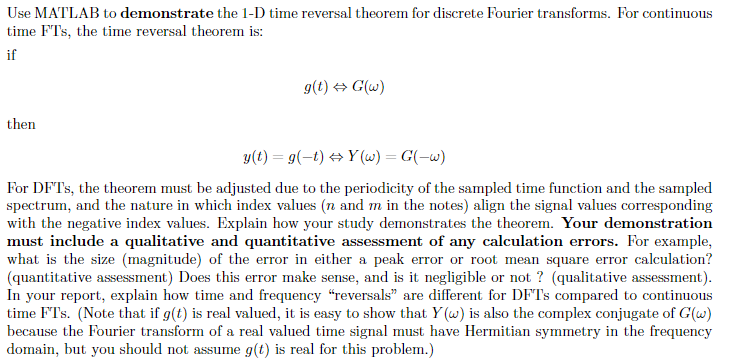

Notes: f(t) <-> f(w);

g(t)=f(-t) <-> G(w) =F(-w)

for DFT: f[n]: list of values at n=0, ending at N=N-1

f[n] = f_0d[n] +f_1d[n-1]+...+f_[N-1] d[n-(N-1)] 

g[n] = f[-n] -> f_0d[-n] + f_1d[-n-1]mod(N) 

g[n] = f_o

clear all;

## Init Functions/Variables


fs = 32;
dt = 1/fs;
w_o = 2*pi;
A = 1;
N= 64; % length of sampled 
n = (0:N-1)*dt;
w = (fs/N*(0:N-1));
%
fn = @(n) A*sin(w_o*n);% Normal samples from d[0]->d[n-(N-1)]
gn = flip(fn(n)); % Flip emulating -n
gn =circshift(gn,1); % Circular shift(mod) to f_o* d[n] 
%In continuous g(t) <-> f(-t), due to  
fw = fft(fn(n),N);
gw = fft(gn,N); 
fw_n = fft(fn(-n),N);
wShift = fs/N*(-N/2:N/2-1); % Centering


## Plots of Time Reversals

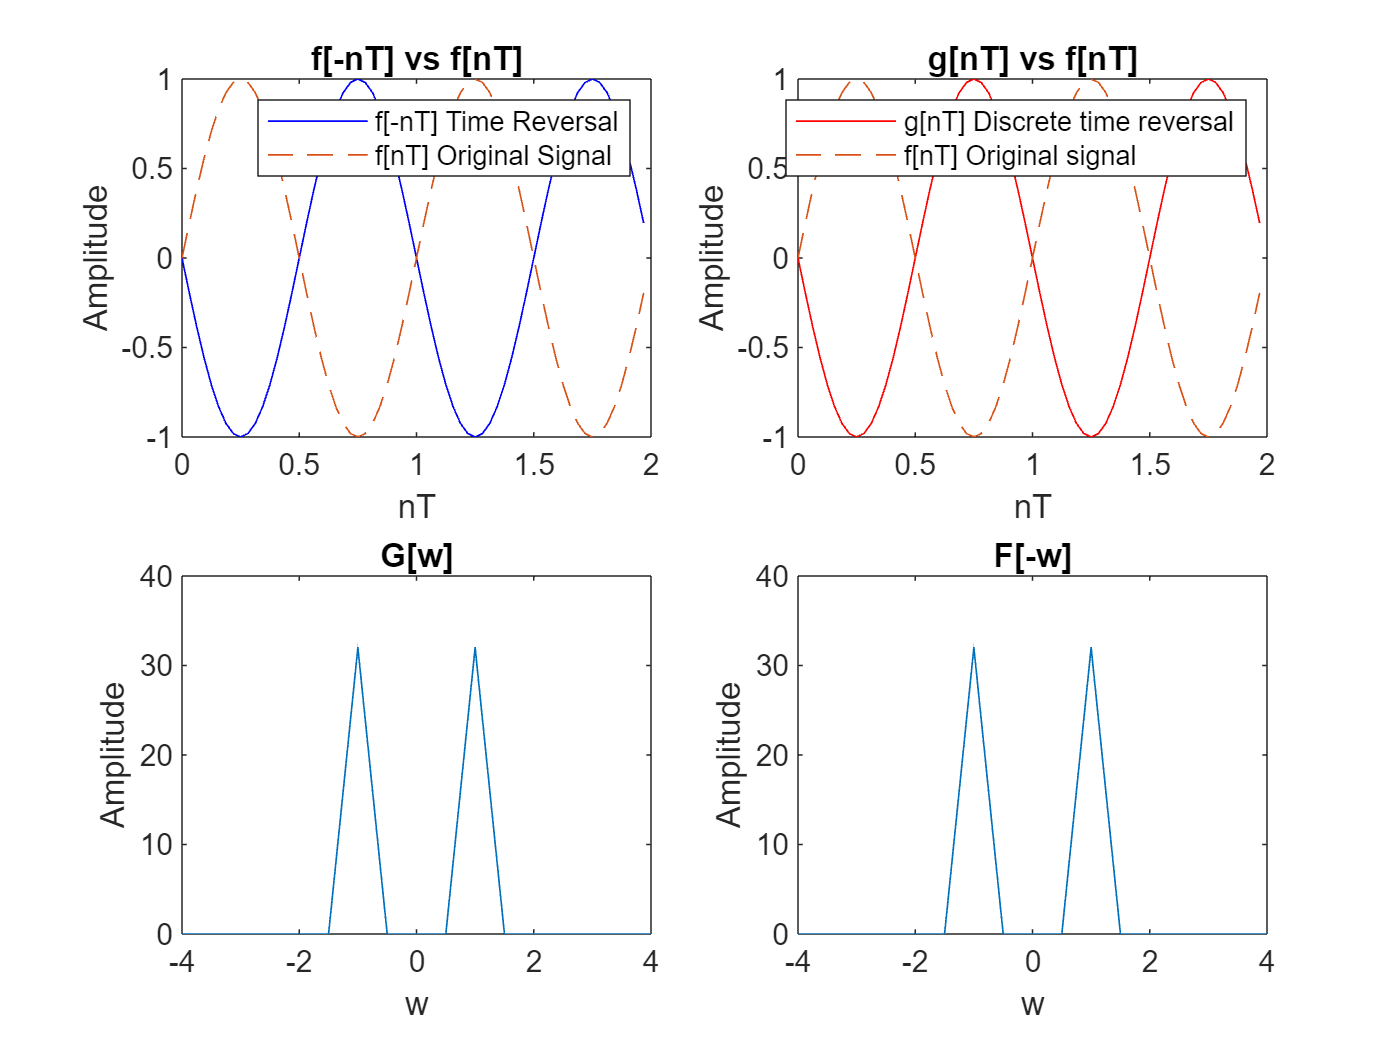

figure;
subplot(2,2,1);
plot(n,fn(-n), 'b');
hold on;
plot(n,fn(n),"--");
title("f[-nT] vs f[nT]")
xlabel("nT");
ylabel("Amplitude");
legend("f[-nT] Time Reversal", "f[nT] Original Signal")
subplot(2,2,2);
plot(n,gn, 'r');
title("g[nT] vs f[nT]");
xlabel("nT");
ylabel("Amplitude");
hold on;
plot(n,fn(n),"--");
legend("g[nT] Discrete time reversal", "f[nT] Original signal")
subplot(2,2,3)
plot(wShift, abs(fftshift(gw))); 
title("G[w]")
xlabel("w");
ylabel("Amplitude");
xlim([-4,4]);
subplot(2,2,4)
plot(wShift, abs(fftshift(fw_n)));
title("F[-w]");
xlabel("w");
ylabel("Amplitude");
xlim([-4,4]);

## Error

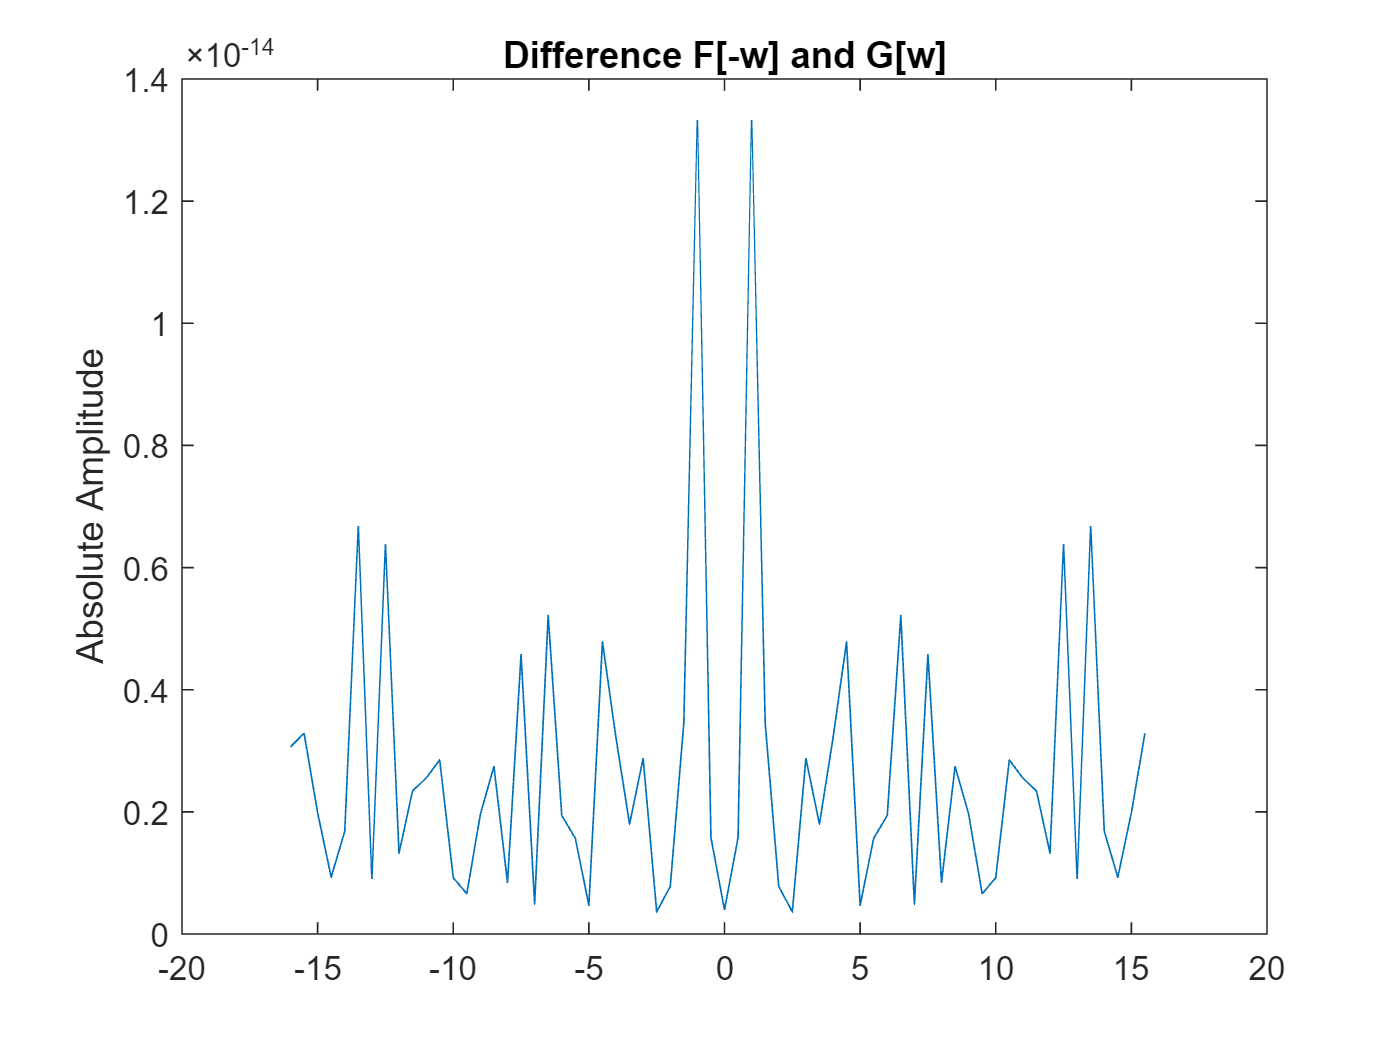


e_gw = rmse(fw_n,gw);
e_s = rmse(fn(-n),gn);
figure;
dif= abs(fw_n-gw);
plot(wShift,fftshift(dif));%Maximal difference at w_o/2
title("Difference F[-w] and G[w]")
ylabel("Absolute Amplitude")

This should be good enough for pt. 2

the error between the F[-M] and G[M] is in the pico units so I would say negligable. The highest peak in error though is around the w_o/2

## Part 3.

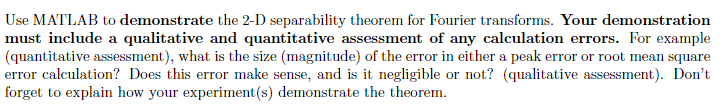

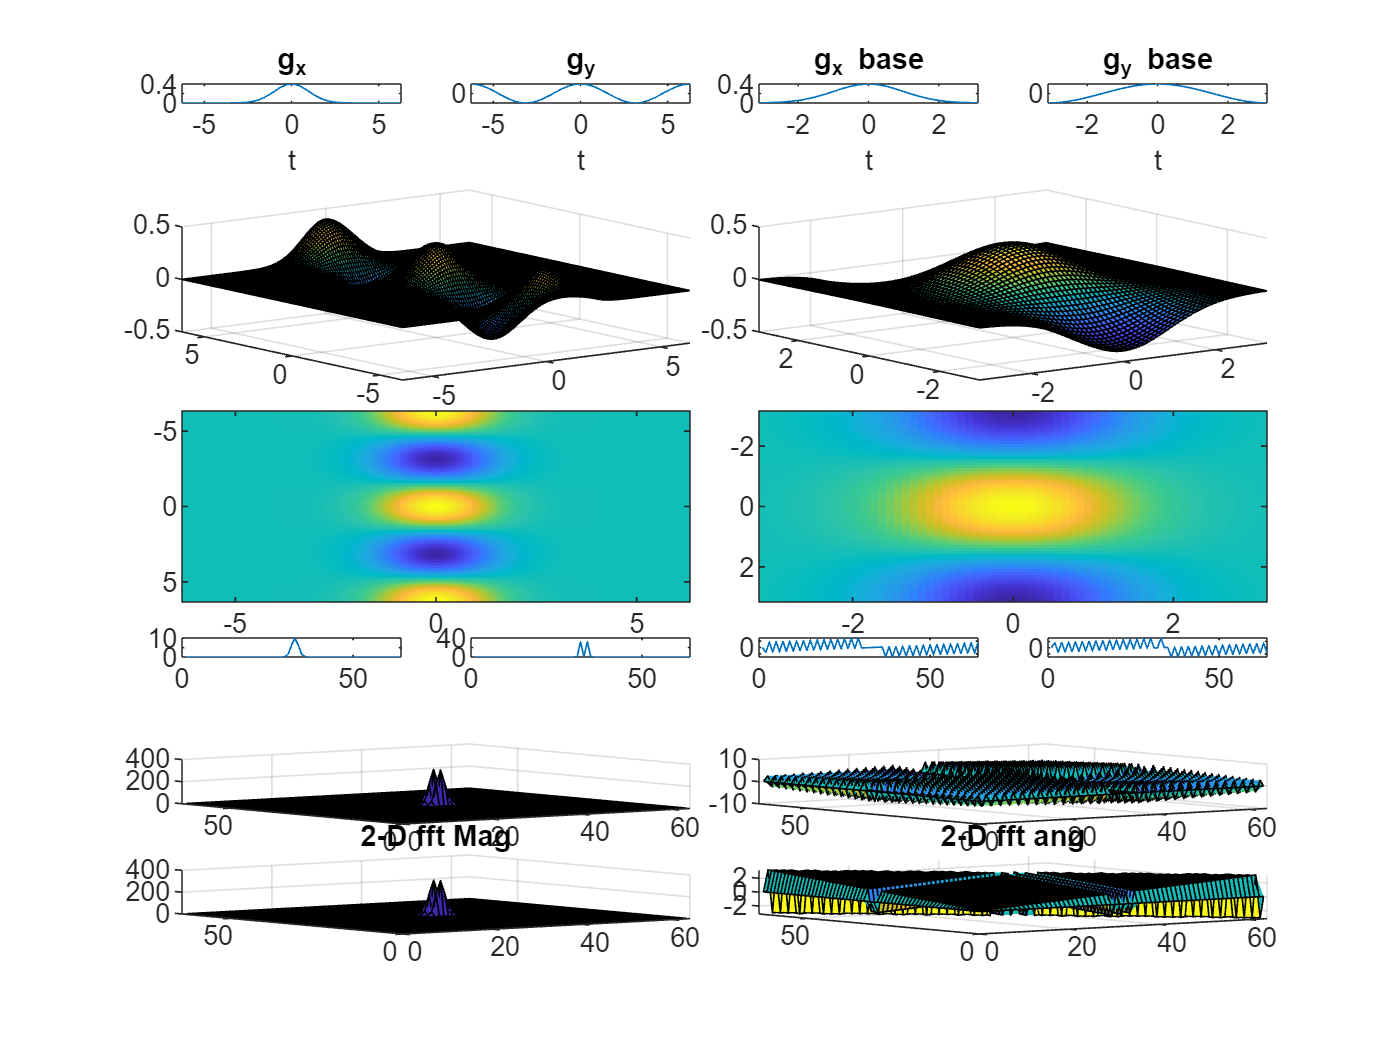

%will generate two 1-D signals, then combine to a 2-D signal, then do 2D
%fft and two 1d fft and compare
%will generate a white gaussian and a sinusoid, each composed of 64 points from
baseValues = linspace(-2*pi, 2*pi, 128); % generating base signal from -2pi to 2pi. will use center -pi to pi portion
delta_t = baseValues(1)-baseValues(2);  % record sample rate

g_x = 1/sqrt(2*pi)*exp(-0.5*baseValues.^2); %generate & plot gaussian curve from -2pi to 2pi
subplot(8,4,1)
plot(baseValues,g_x)      
xlabel('t')
title('g_x')
subplot(8,4,3)
plot(baseValues(33:96), g_x(33:96)) %plot gaussian curve from -pi to pi
xlabel('t')
title('g_x base')

g_y = cos(baseValues);  %generate and plot cosine from -2pi to 2pi
subplot(8,4,2)
plot(baseValues,g_y)
xlabel('t')
title('g_y')
subplot(8,4,4)
plot(baseValues(33:96), g_y(33:96)) %plot cosine from -pi to pi
xlabel('t')
title('g_y base')

[tempX, tempY] = meshgrid(g_x, g_y);                    %generate fully sized array of X and Y to prep for 3D
[tempXX, tempYY] = meshgrid(g_x(33:96), g_y(33:96));    %same as above but limited to -pi to pi

g_f = tempX.*tempY;     % generate 2d plots for both limits and plot in 3d and in heat map for visualization
g_ff = tempXX.*tempYY;  % plotted both -2pi to 2pi and -pi to pi plots to imply the signals are repeating 
subplot(8,4,[5,6,9,10]) % and just a window of the repeating portion is being observed 
surf(baseValues, baseValues, g_f)
subplot(8,4,[13,14,17,18])
imagesc(baseValues, baseValues, g_f)
subplot(8,4,[7,8,11,12])
surf(baseValues(33:96), baseValues(33:96), g_ff)
subplot(8,4,[15,16,19,20])
imagesc(baseValues(33:96), baseValues(33:96), g_ff)

G_x = fft(fftshift(g_x(33:96)));    % generate the 1D ffts using fftshift to maintin zero
G_y = fft(fftshift(g_y(33:96)));    % position from the center of the array
subplot(8,4,21)
plot(ifftshift(abs(G_x)))           % place ifftshift on frequency domain to show negative to positive freq 
subplot(8,4,22)                     % (mostly to show gaussian in, gaussian out)
plot(ifftshift(abs(G_y)))
subplot(8,4,23)
plot(ifftshift(angle(G_x)))
subplot(8,4,24)
plot(ifftshift(angle(G_y)))

[fXmag,fYmag] = meshgrid(ifftshift(abs(G_x)), ifftshift(abs(G_y))); 
G_f_mag = fXmag.*fYmag;     %repeat process from start of problem to generate 2D fft as the 1D fft's multiplied
[fXang,fYang] = meshgrid(ifftshift(angle(G_x)), ifftshift(angle(G_y)));
G_f_angle = fXang.*fYang;
subplot(8,4,[25,26])
surf(G_f_mag)
subplot(8,4,[27,28])
surf(G_f_angle)

G_ff = fft2(g_ff);      %generate 2D fft directly from the 2D time domain plot for comparison
subplot(8,4,[29,30])
surf(fftshift(abs(G_ff)))
title('2-D fft Mag')
subplot(8,4,[31,32])
surf(fftshift(angle(G_ff)))
title('2-D fft ang')

## Part 4.

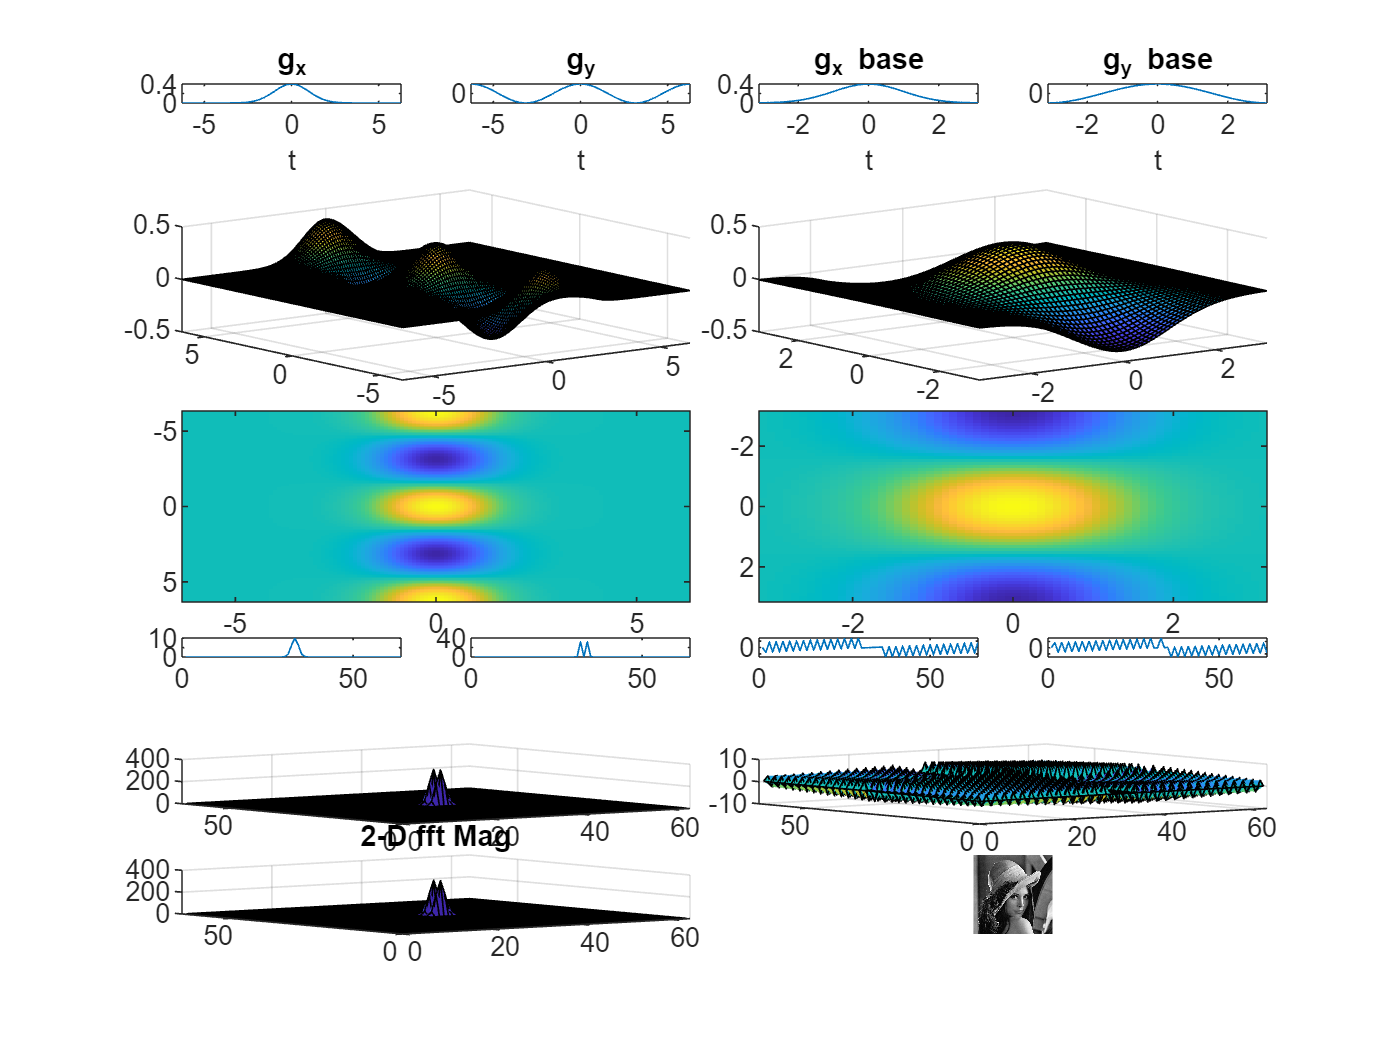

%Load and display grayscale 'Lena' image file
img = rescale(im2gray(imread('img_gray.png')));
imshow(img)

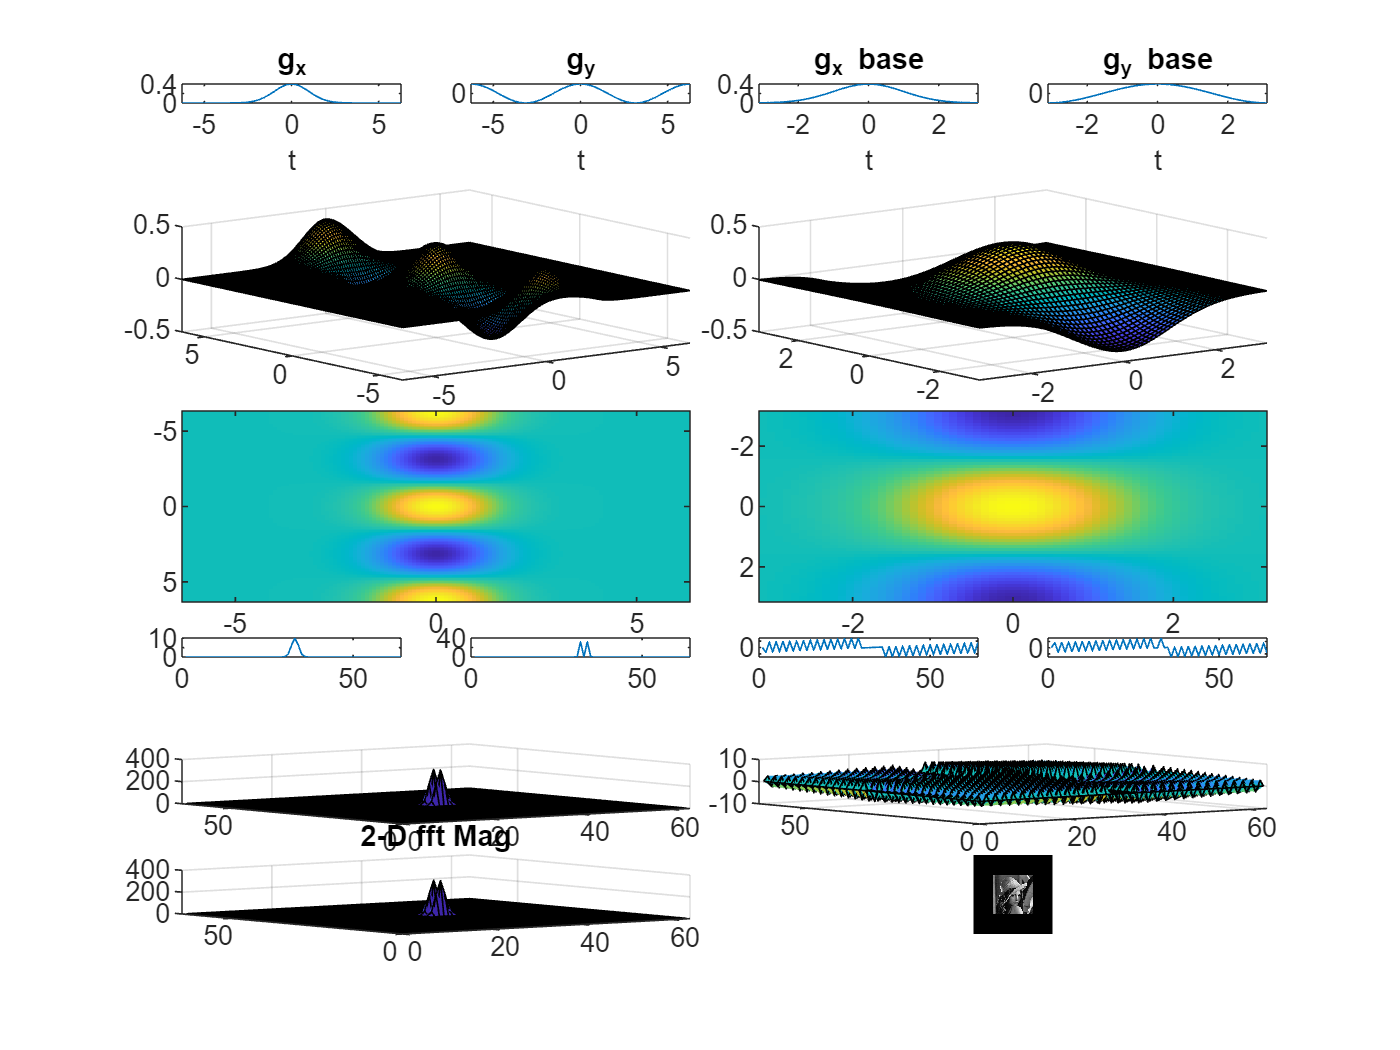

%Remove first row and column of img to create an array with odd dimensions
%Going from 512 x 512 to 511 x 511
img(1,:) = [];
img(:,1) = [];

%Pad image with zeros to produce new image of dimension (2^p + 1) x (2^p + 1)
%In this case, p=10 and padded img is 1025 x 1025
padding = ((2^10) + 1 - size(img,1))/2;
img_pad = padarray(img, [padding, padding]);

%Display padded image
imshow(img_pad)

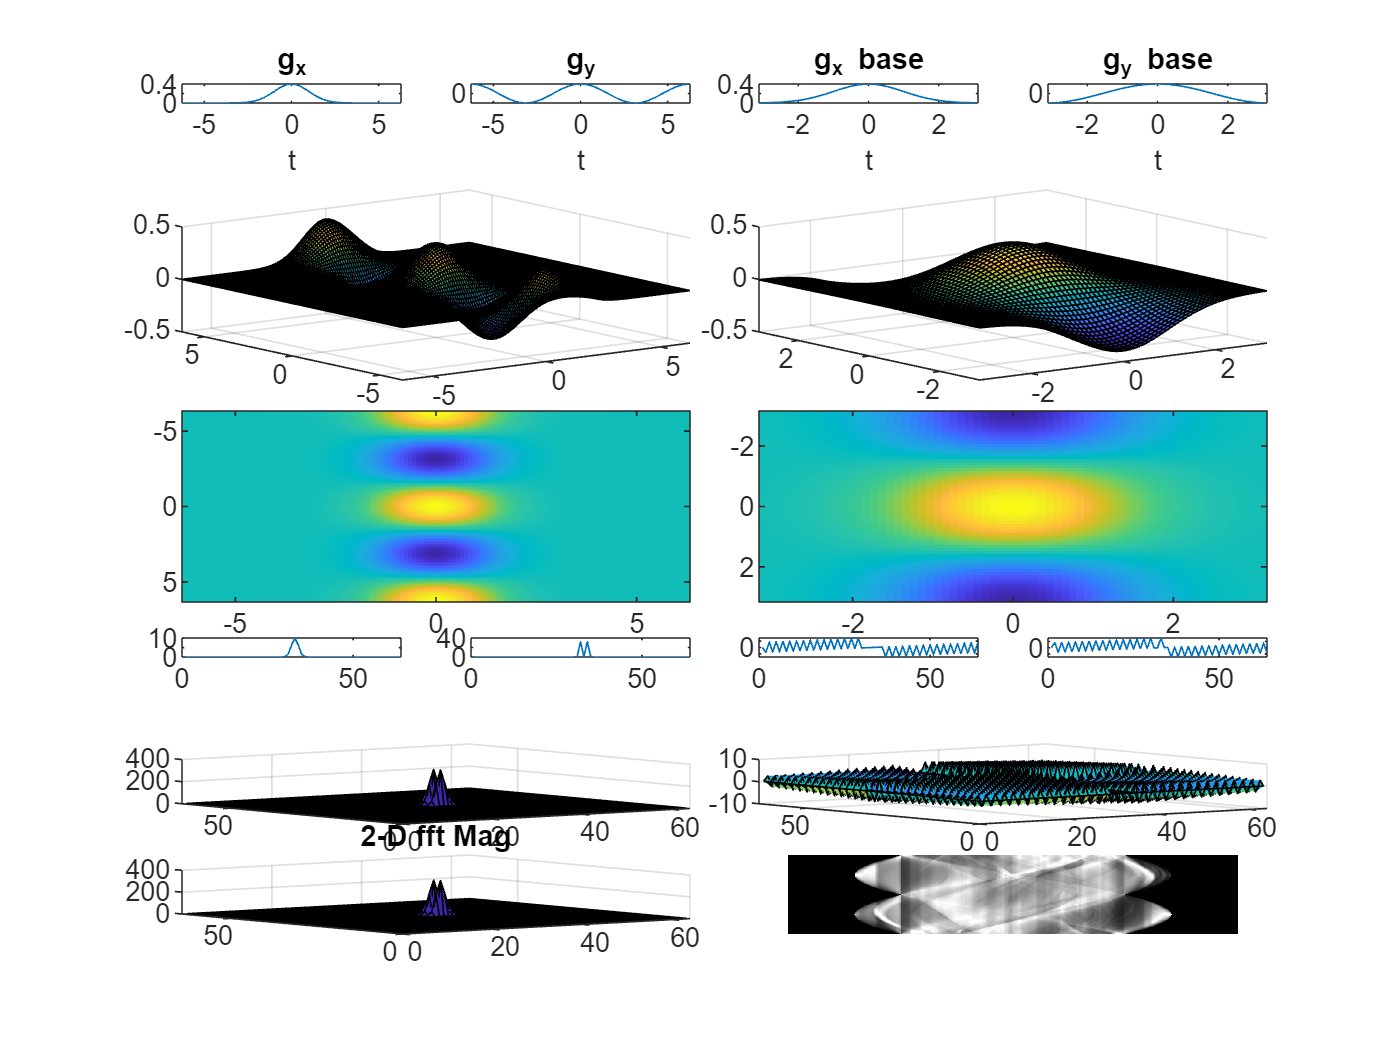

%Set rotation angle step to 1 degree
del_phi = 1;

%Define projection matrix
p_phi = [];

%Simulate projections by rotating img and summing down columns
for phi_temp = 0:del_phi:179
    img_temp = imrotate(img_pad, phi_temp, 'crop');
    p_phi(phi_temp+1, :) = sum(img_temp);
end

%Display normalized projection matrix (sinogram)
imshow(p_phi./max(p_phi))

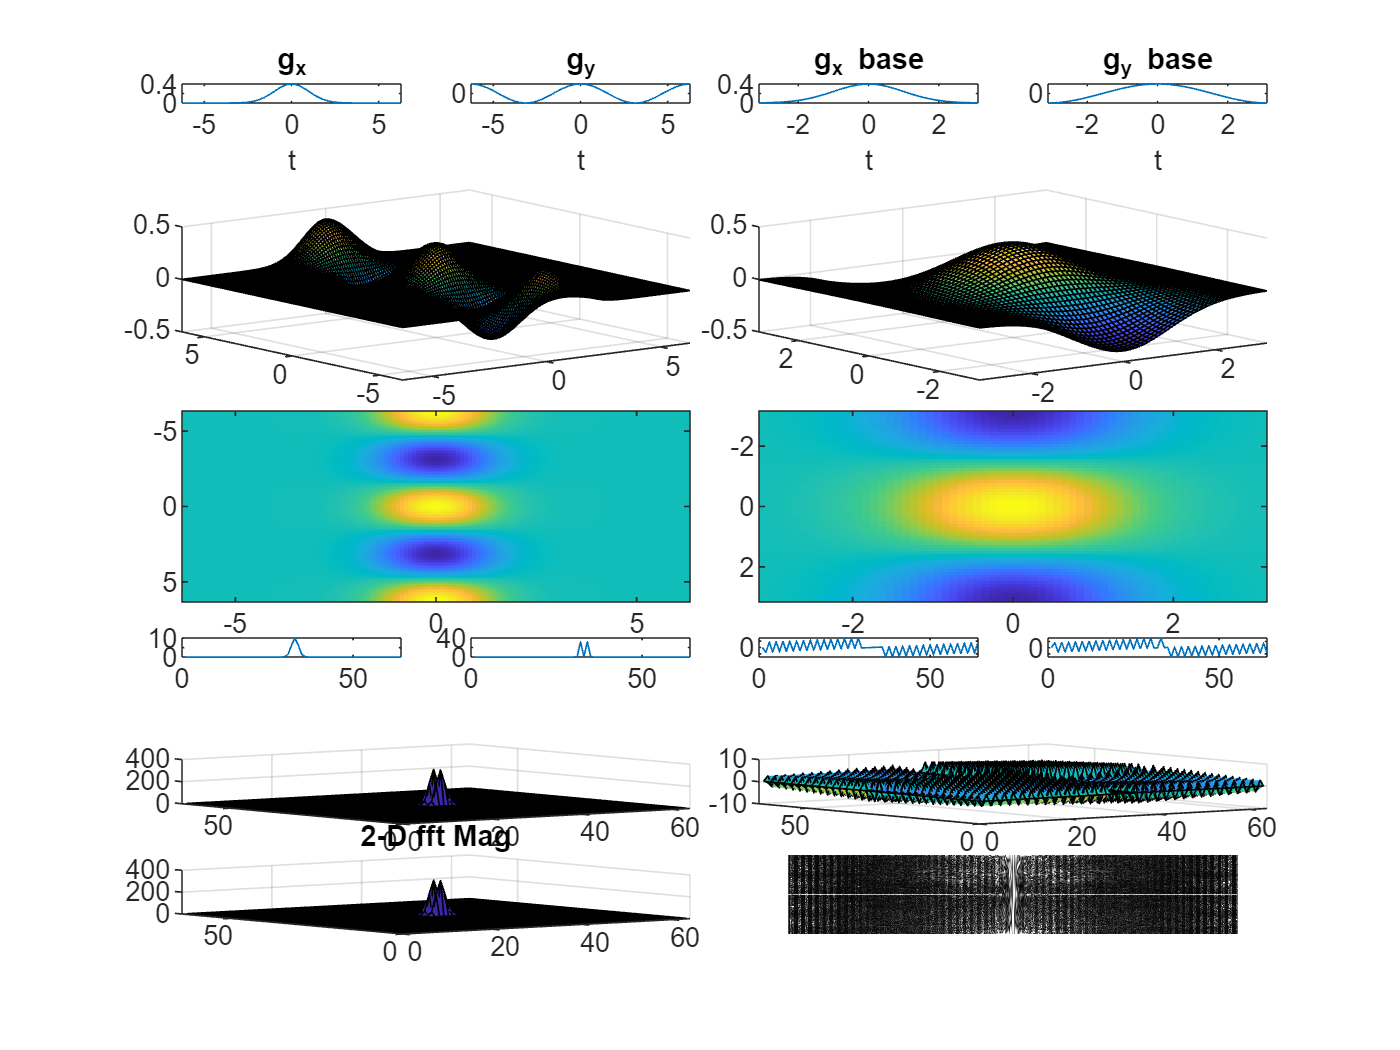

%Remove last column of proj mtx so 2nd dimension = 2^10
p_phi(:,2^10 + 1) = [];

%Perform fftshift followed by fft across the rows (central slices)
p_phi = fftshift(p_phi, 2);
P_phi = fft(p_phi,[],2);
P_phi = fftshift(P_phi, 2);

%Display normalized central slice matrix
imshow(abs(P_phi)./max(abs(P_phi)))

%Create arrays for use in griddata
phi = [0:1:179]';
omega_x_prime = [-size(P_phi,2)/2 : 1 : size(P_phi,2)/2 - 1];
omega_x_known = cosd(phi)*omega_x_prime;
omega_y_known = sind(phi)*omega_x_prime;
values_known = P_phi;
omega_x_target = ones(size(omega_x_prime,1),1)'*omega_x_prime;
omega_y_target = omega_x_target';

%Estimate F with linear interpolation of central slices
F_lin = griddata(omega_x_known,omega_y_known,values_known,omega_x_target,omega_y_target,'linear');

%Replace NaN values with 0
NaNs = isnan(F_lin);
F_lin(NaNs) = 0;

%Estimate F with nearest neighbor interpolation of central slices
F_near = griddata(omega_x_known,omega_y_known,values_known,omega_x_target,omega_y_target,'nearest');

%Replace NaN values with 0
NaNs = isnan(F_near);
F_near(NaNs) = 0;

%Estimate F with cubic interpolation of central slices
F_cub = griddata(omega_x_known,omega_y_known,values_known,omega_x_target,omega_y_target,'cubic');

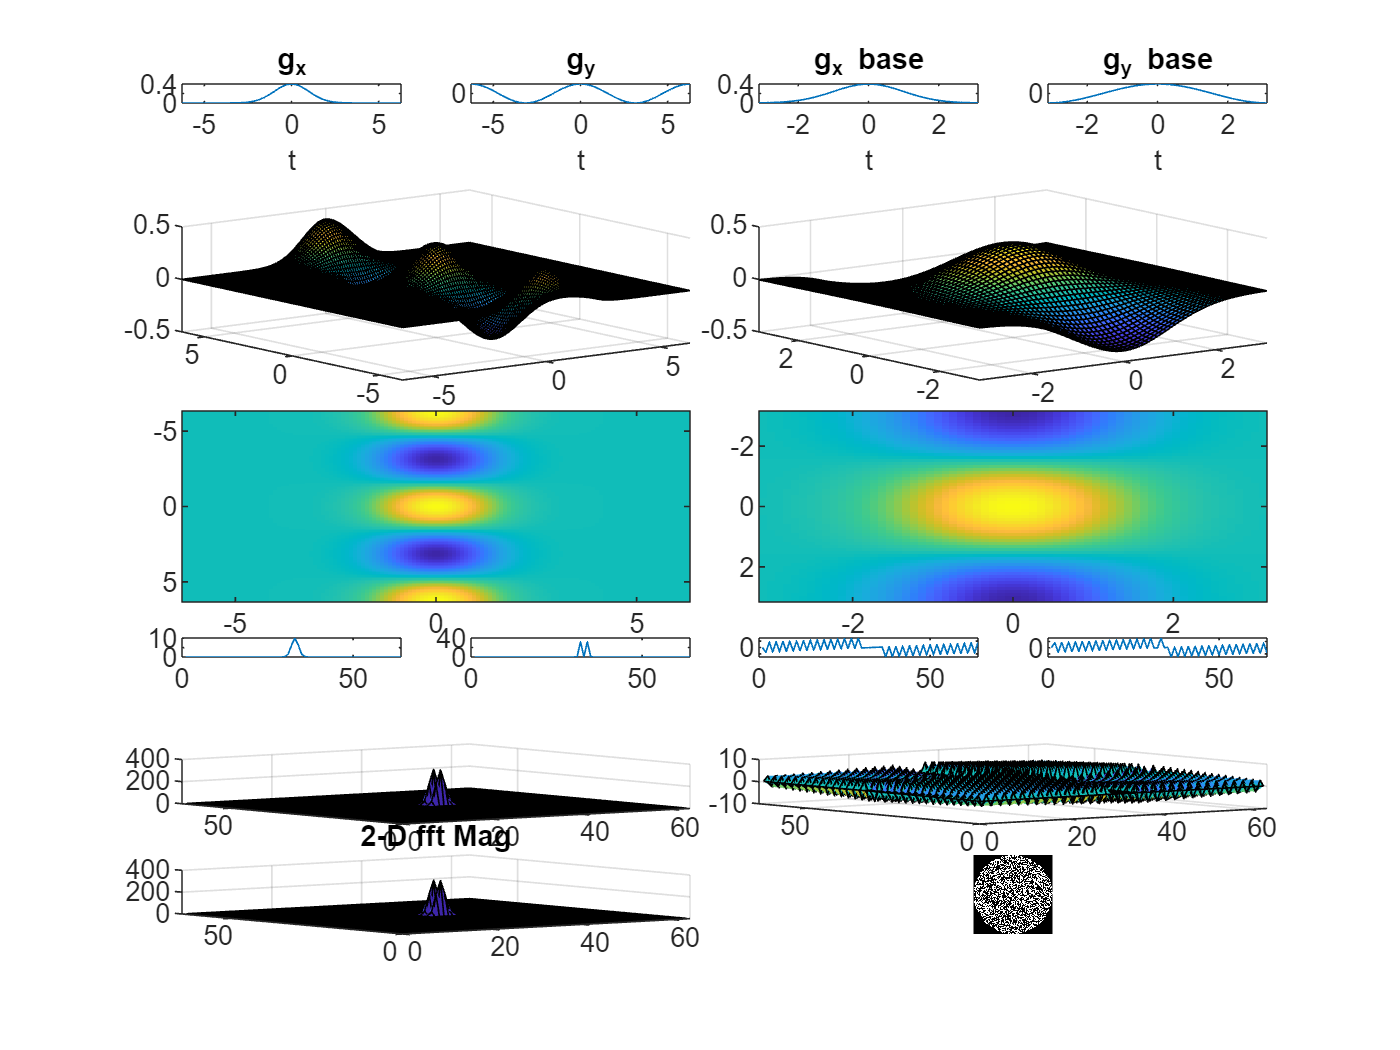


%Replace NaN values with 0
NaNs = isnan(F_cub);
F_cub(NaNs) = 0;

%Display real part of F w/ linear interpolation
imshow(F_lin)

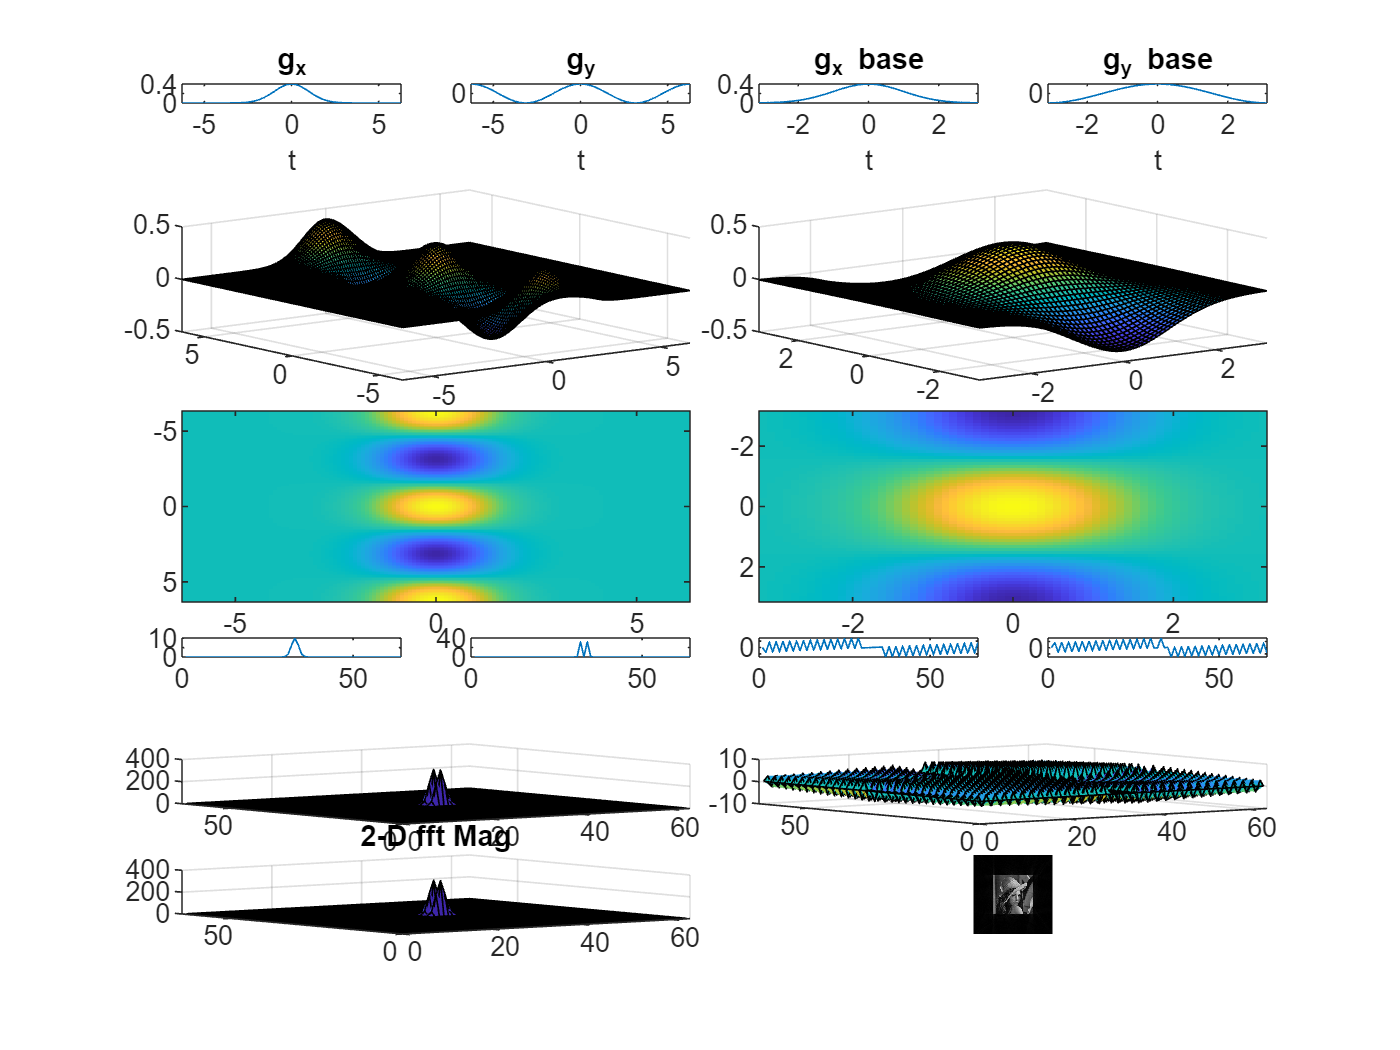


%Estimate f using 2D ifft of F for each interpolation type
f_lin = fftshift(ifft2(fftshift(F_lin)));
f_near = fftshift(ifft2(fftshift(F_near)));
f_cub = fftshift(ifft2(fftshift(F_cub)));

%Display magnitude of f w/ linear interpolation
imshow(rescale(abs(f_lin)))

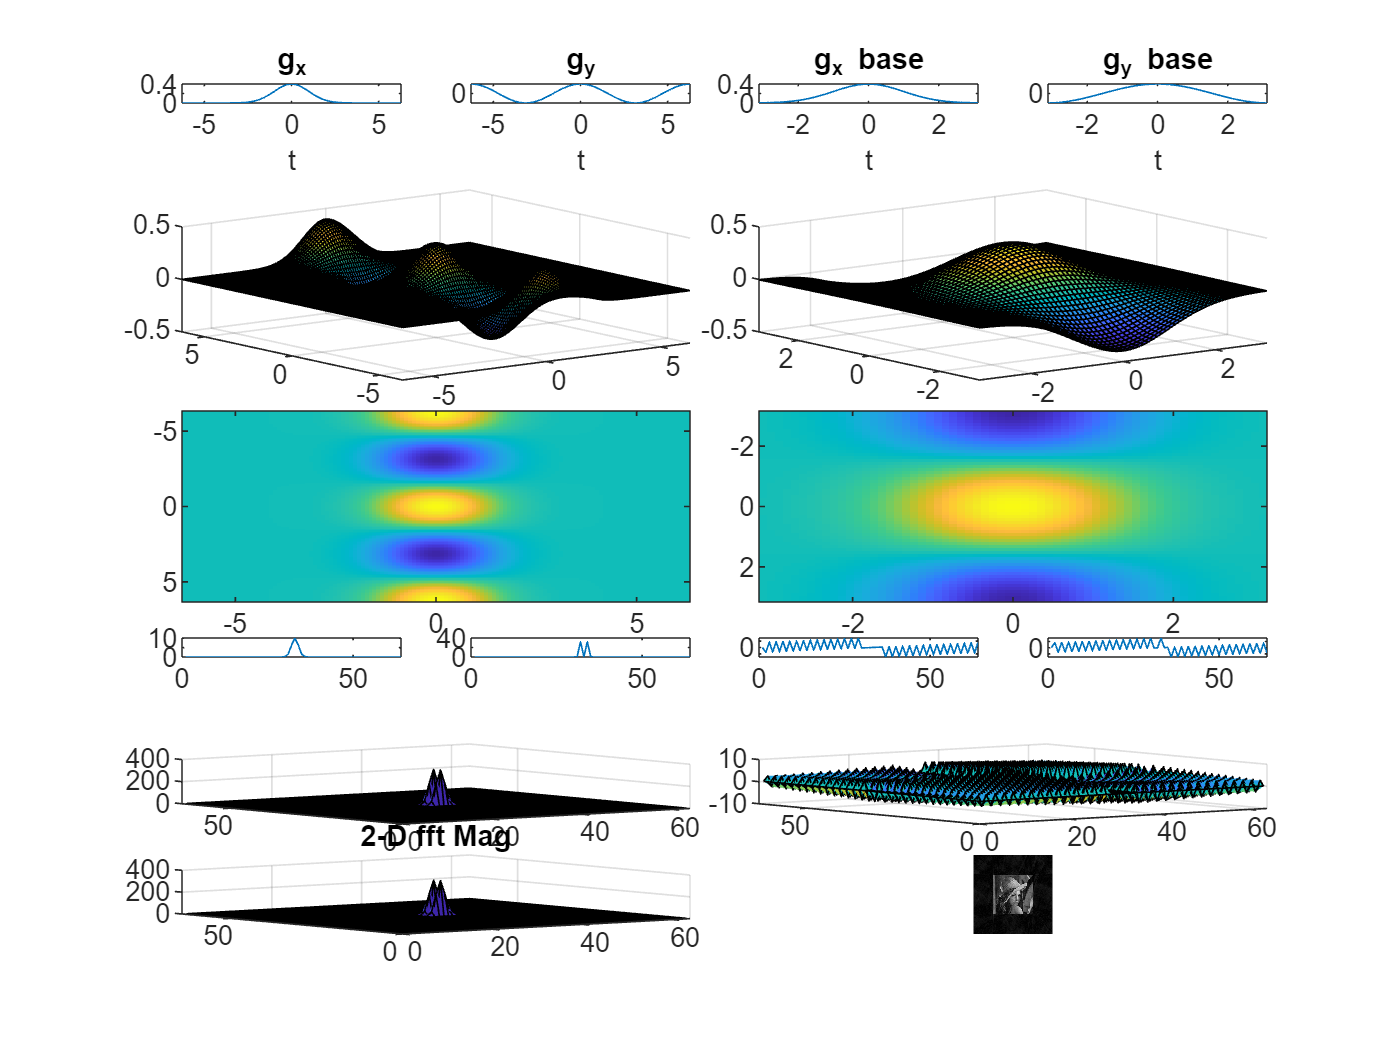

%Display magnitude of f w/ nearest neighbor interpolation
imshow(rescale(abs(f_near)))

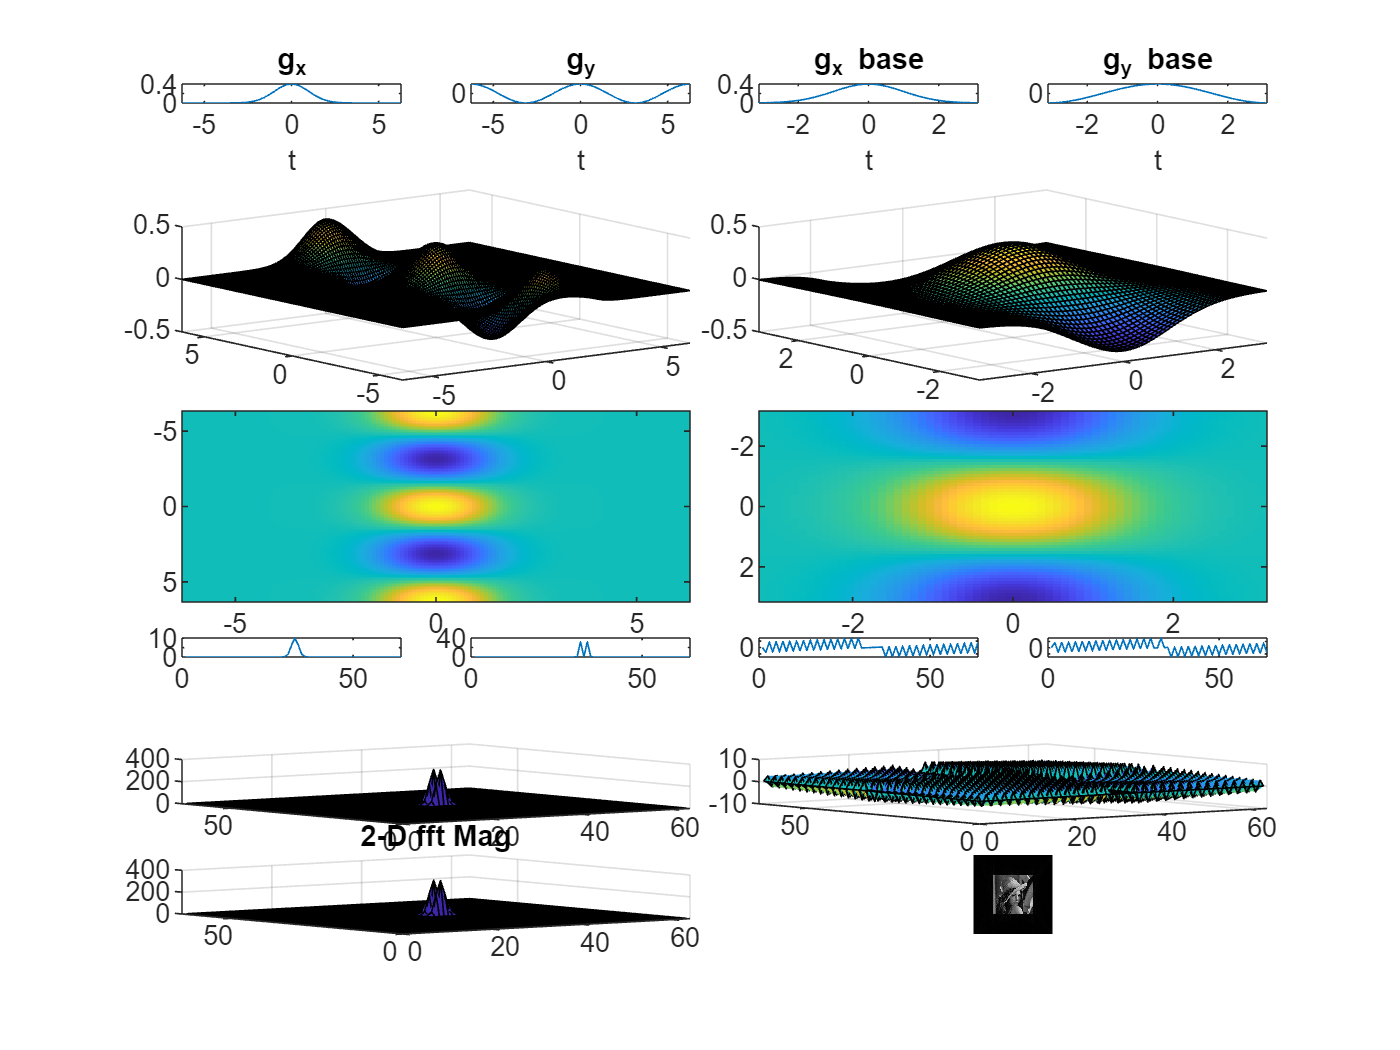


%Display magnitude of f w/ linear interpolation
imshow(rescale(abs(f_cub)))

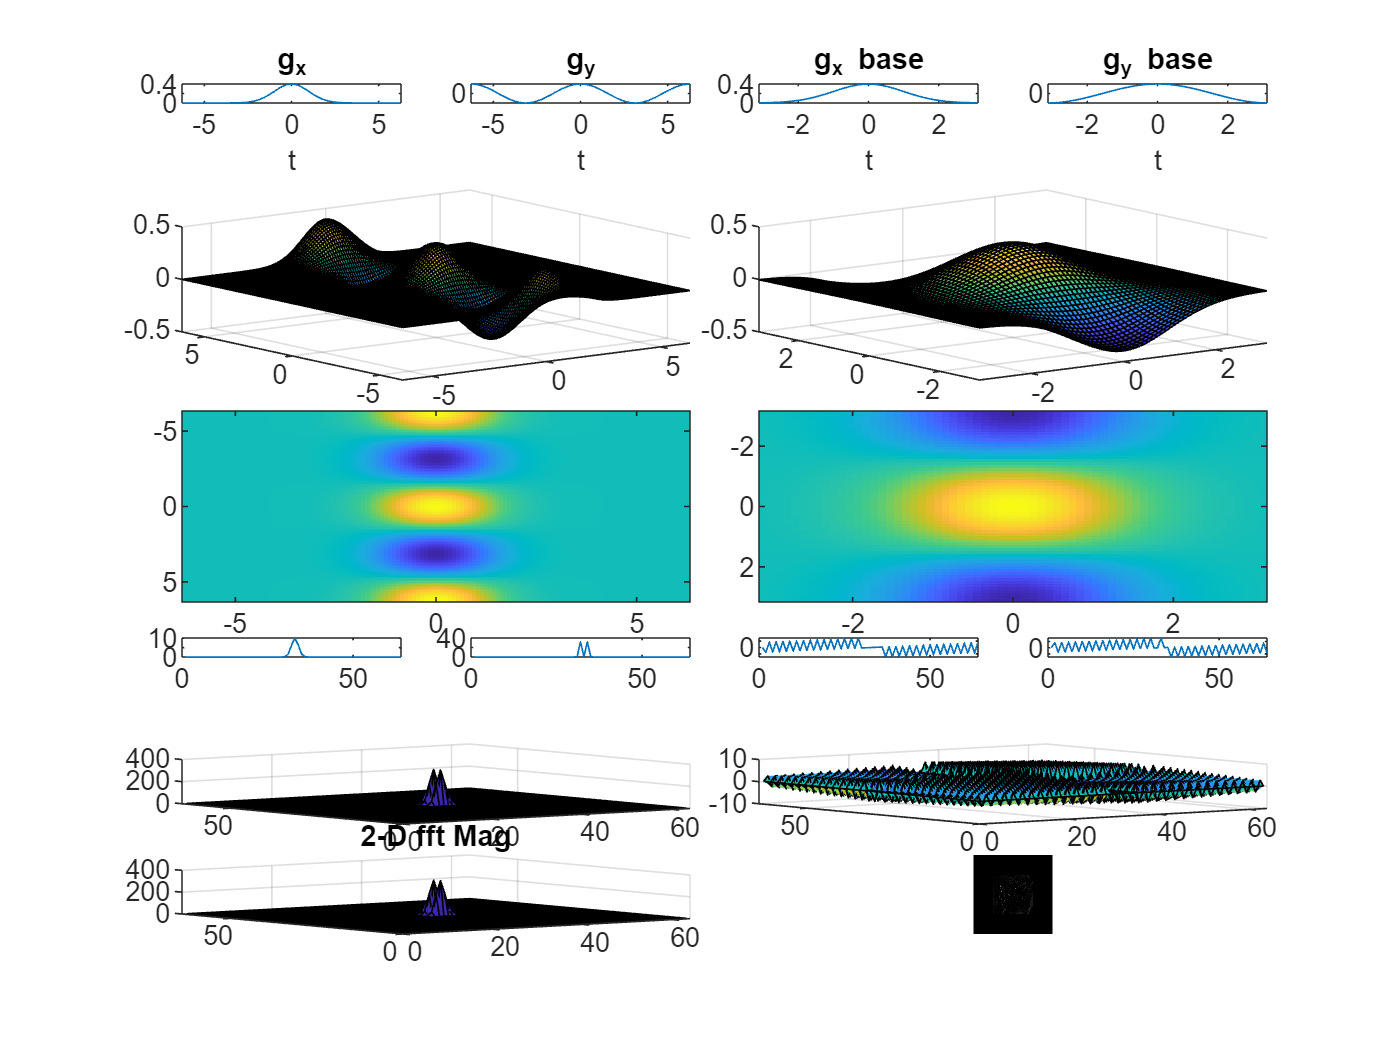

%Remove 1st row and column of zeros in original padded image
%so the dimensions will match with reconstructed images
img_pad(1,:) = [];
img_pad(:,1) = [];

%Calculate error magnitude matrix of reconstructed images for each interpolation type
err_lin = double(img_pad) - abs(f_lin);
err_cub = double(img_pad) - abs(f_cub);
err_near = double(img_pad) - abs(f_near);

%Display error magnitude plots for each interpolation type
imshow(err_lin)

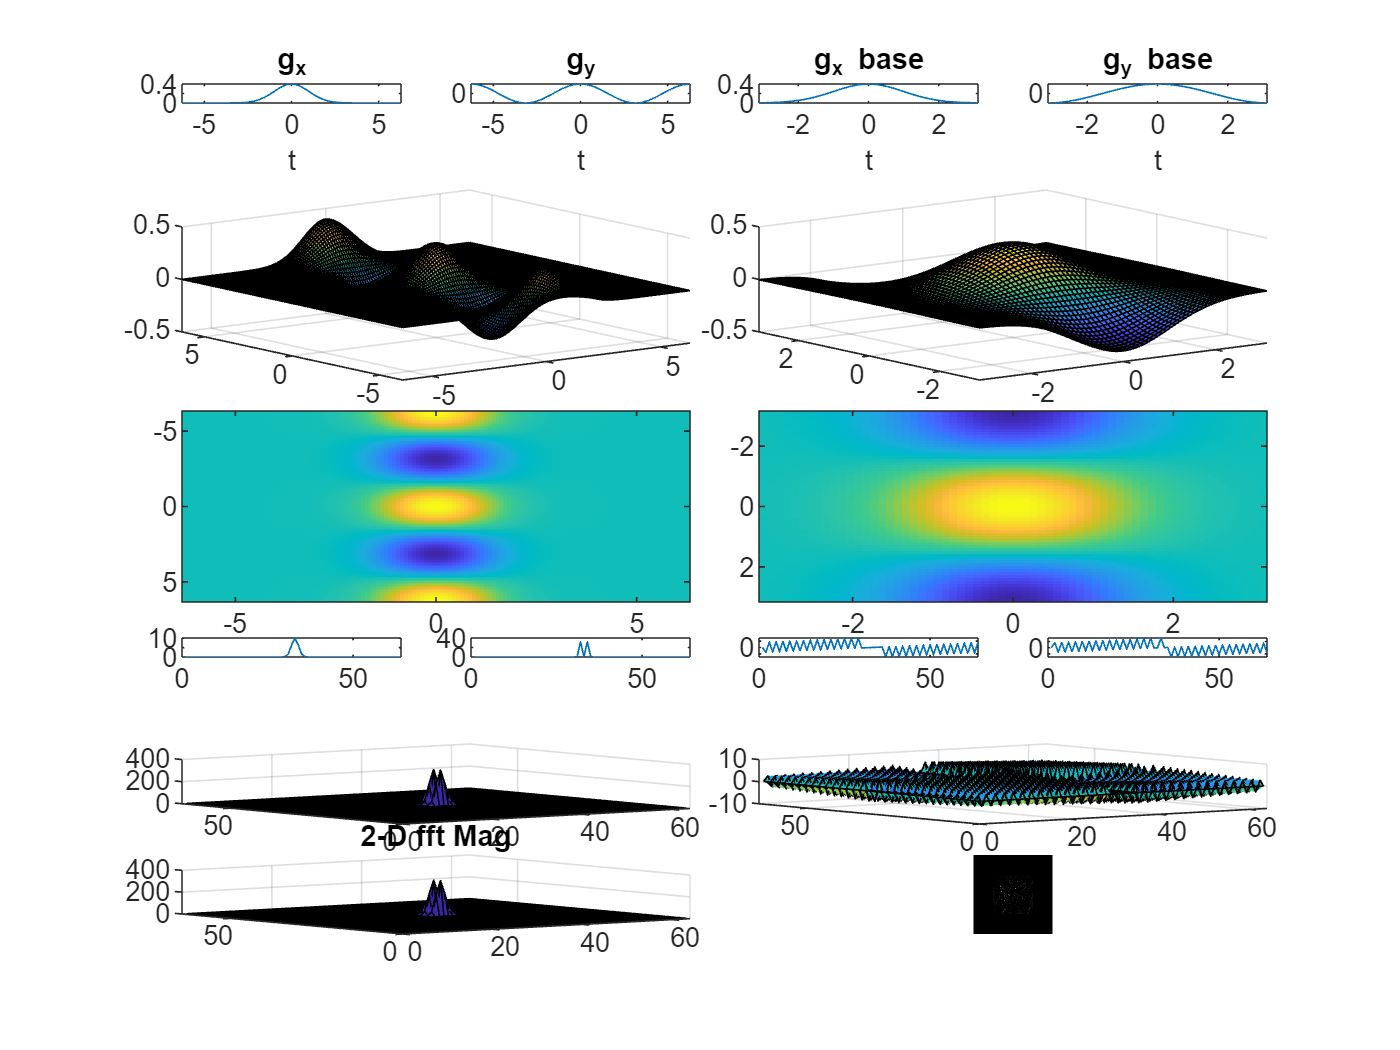

imshow(err_cub)

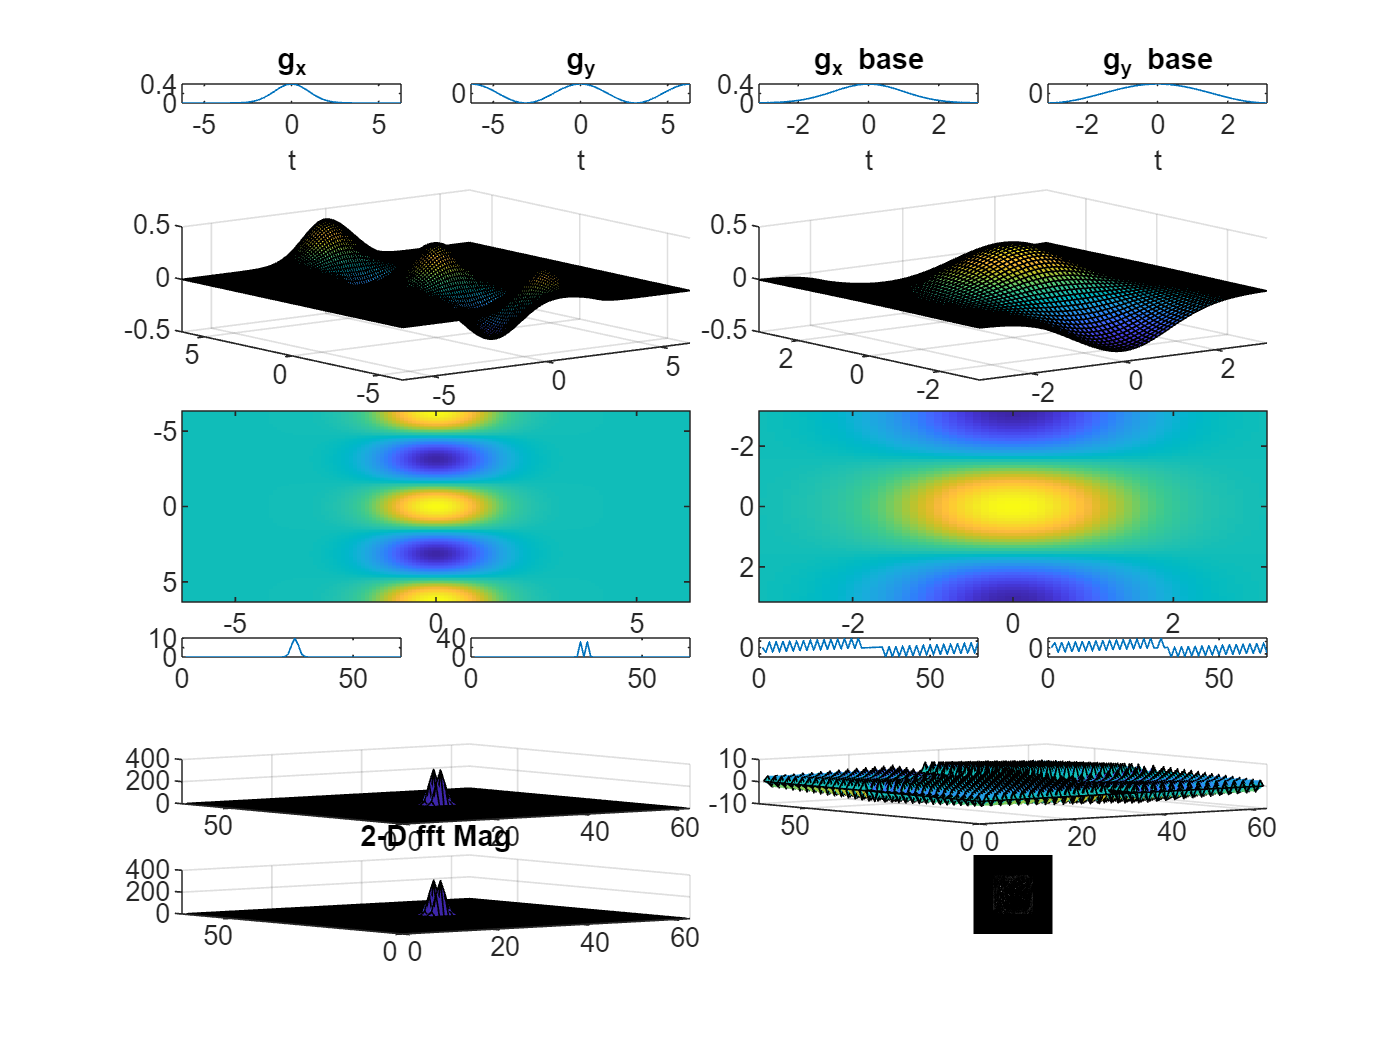

imshow(err_near)

%Calculate mean squared error (MSE) between each reconstruction and original img
mse_lin = immse(double(img_pad), f_lin);
mse_cub = immse(double(img_pad), f_cub);
mse_near = immse(double(img_pad), f_near);

%Print MSEs
fprintf('\n The mean-squared error for linear interpolation is %0.4f\n \n The mean-squared error for cubic interpolation is %0.4f\n \n The mean-squared error for nearest neighbor interpolation is %0.4f\n', mse_lin, mse_cub, mse_near);


 The mean-squared error for linear interpolation is 0.0017
 
 The mean-squared error for cubic interpolation is 0.0016
 
 The mean-squared error for nearest neighbor interpolation is 0.0050
